R = 100; C = .02; qo = 5; a = 1; w = 1;

## a

V = @(t) a*sin(w*t)

V = function_handle with value:
    @(t)a*sin(w*t)


## b

dq1 = @(t,q) (V(t)-q/C)/R

dq1 = function_handle with value:
    @(t,q)(V(t)-q/C)/R


## c

tspan = [0 10]

tspan =      0    10


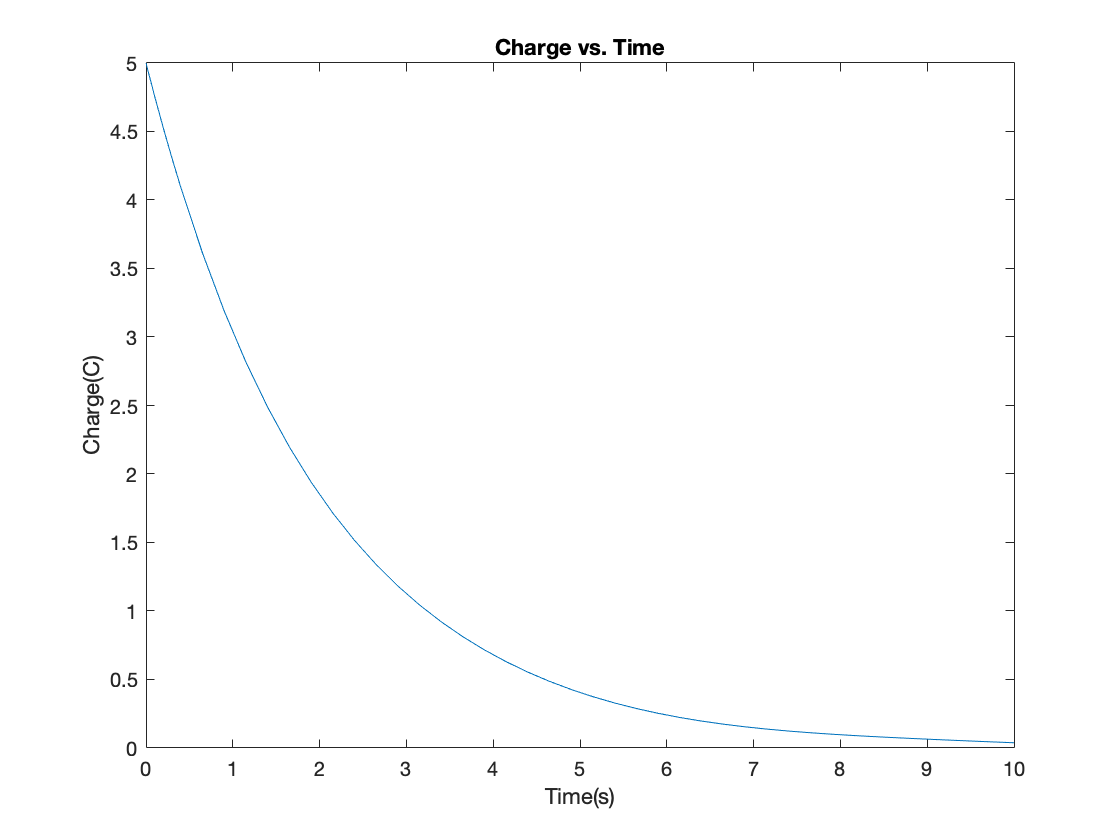

[t, q] = ode45(@(t,q) dq1(t,q),tspan,qo);
plot(t,q)
xlabel('Time(s)');
ylabel('Charge(C)');
title('Charge vs. Time');

## d

dq2 = @(q,V) (V-q/C)/R

dq2 = function_handle with value:
    @(q,V)(V-q/C)/R


## e


[t q] = ode45(@(t,q) dq2(q,V(t)),tspan,qo);
plot(t,q)
xlabel('Time(s)');
ylabel('Charge(C)');
title('Charge vs. Time');
hold on

## f

dq3 = @(q) dq2(q,0)

dq3 = function_handle with value:
    @(q)dq2(q,0)


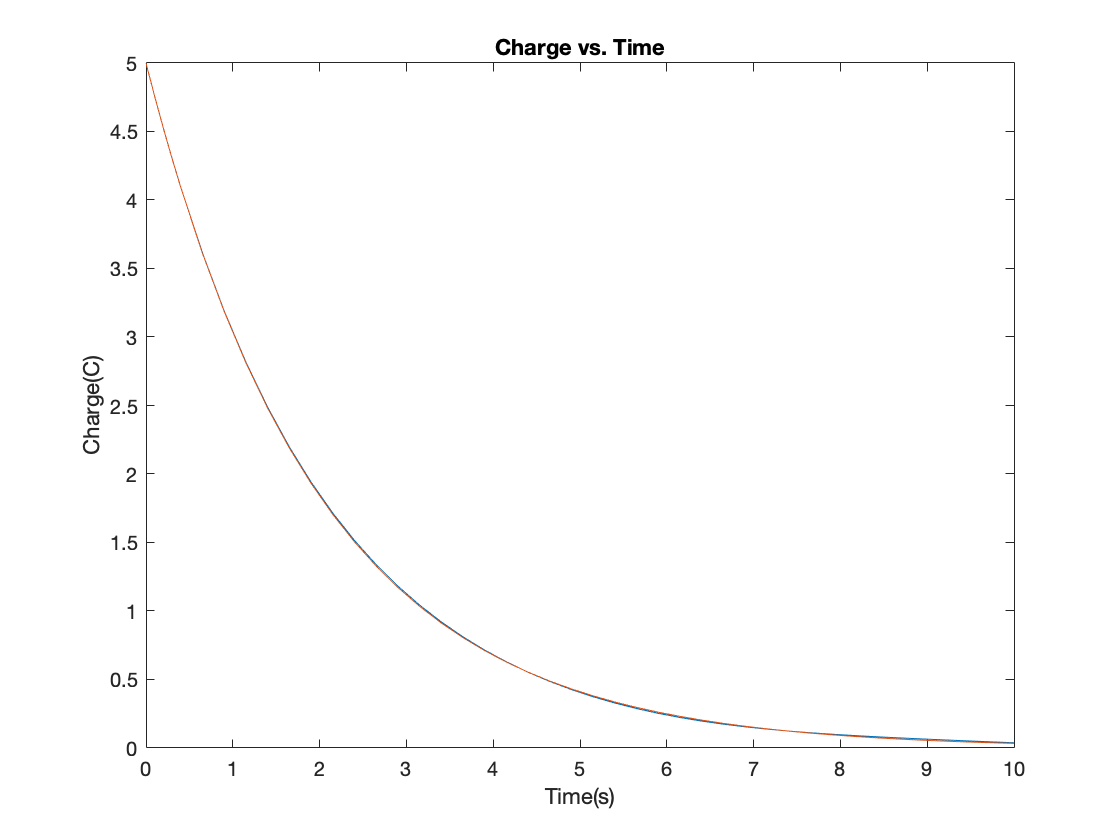

[t q] = ode45(@(t,q) dq3(q),tspan,qo);
plot(t,q)

## g

dq = @(q,R,C) -q/(R*C)

dq = function_handle with value:
    @(q,R,C)-q/(R*C)


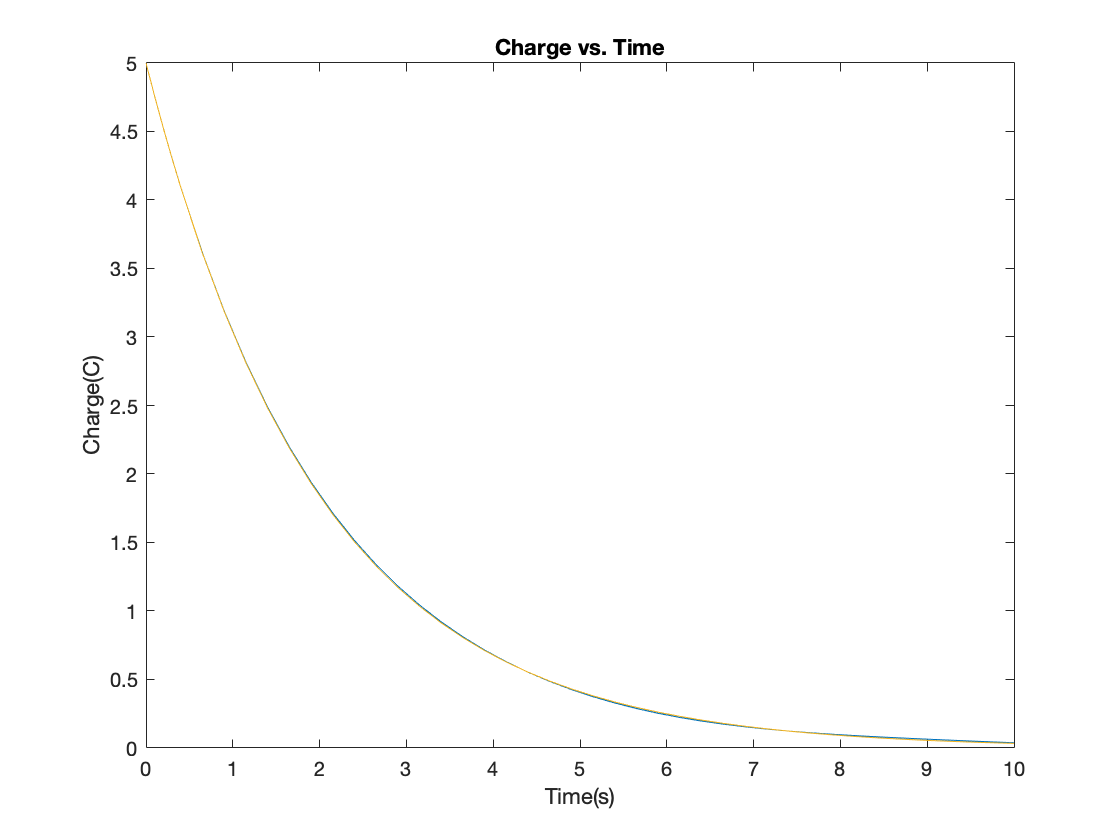

[t q] = ode45(@(t,q) dq(q,R,C),tspan,qo);
plot(t,q)